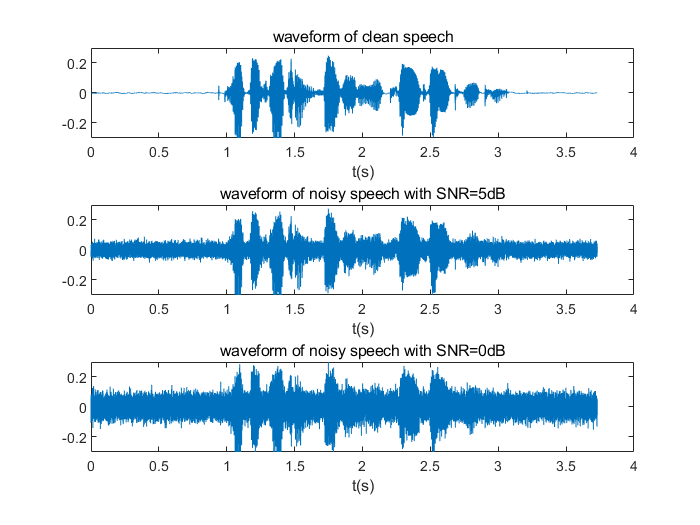

[s,fs]=audioread('mhint_01_01.wav');
y_5=awgn(s,5,'measured');
y_0=awgn(s,0,'measured');
equalize_y_5=y_5/norm(y_5)*norm(s);
equalize_y_0=y_0/norm(y_0)*norm(s);

%plot waveform
figure
subplot(3,1,1);
t_s=0:1/fs:(length(s)-1)/fs;
plot(t_s,s);
xlabel('t(s)');
title('waveform of clean speech');
axis([0 4 -0.3 0.3]);
subplot(3,1,2);
t_5=0:1/fs:(length(y_5)-1)/fs;
plot(t_5,y_5);
xlabel('t(s)');
title('waveform of noisy speech with SNR=5dB');
axis([0 4 -0.3 0.3]);
subplot(3,1,3);
t_0=0:1/fs:(length(y_0)-1)/fs;
plot(t_0,y_0);
xlabel('t(s)');
title('waveform of noisy speech with SNR=0dB');
axis([0 4 -0.3 0.3]);

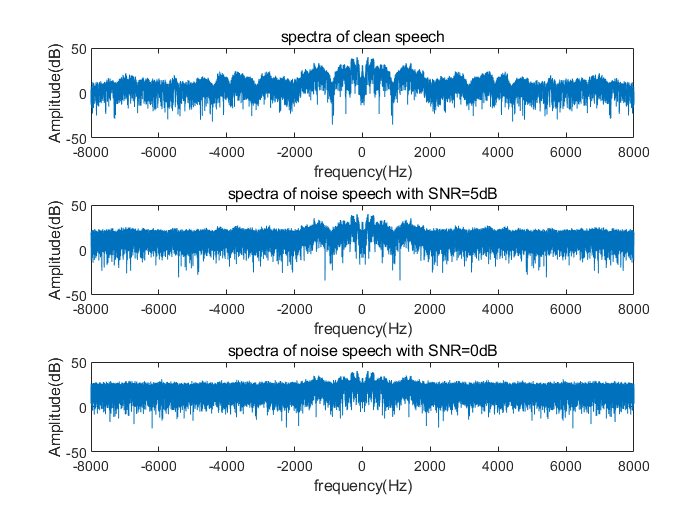


%plot spectra
figure
subplot(3,1,1);
n_s=length(s);
plot((-n_s/2:n_s/2-1)*fs/n_s,mag2db(abs(fftshift(fft(s)))));
xlabel('frequency(Hz)');
ylabel('Amplitude(dB)');
title('spectra of clean speech');
subplot(3,1,2);
n_y_5=length(y_5);
plot((-n_y_5/2:n_y_5/2-1)*fs/n_y_5,mag2db(abs(fftshift(fft(y_5)))));
xlabel('frequency(Hz)');
ylabel('Amplitude(dB)');
title('spectra of noise speech with SNR=5dB');
axis([-8000 8000 -50 50])
subplot(3,1,3);
n_y_0=length(y_0);
plot((-n_y_0/2:n_y_0/2-1)*fs/n_y_0,mag2db(abs(fftshift(fft(y_0)))));
xlabel('frequency(Hz)');
ylabel('Amplitude(dB)');
title('spectra of noise speech with SNR=0dB');
axis([-8000 8000 -50 50])

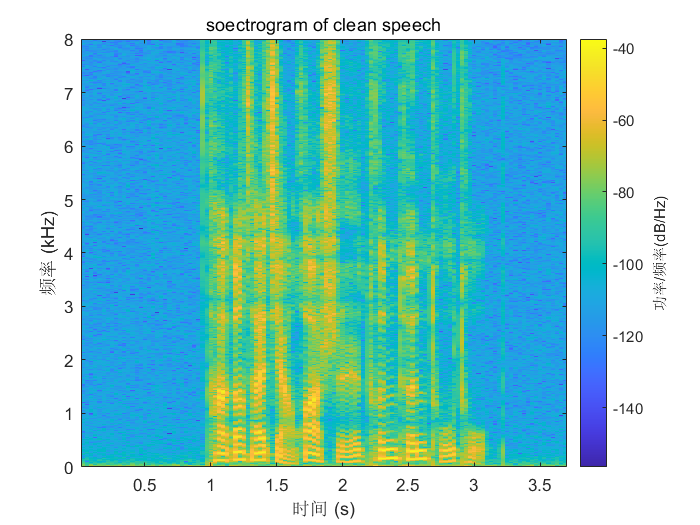


%plot spectra
figure
spectrogram(s,1000,[],59670,fs,'yaxis');
title('soectrogram of clean speech');

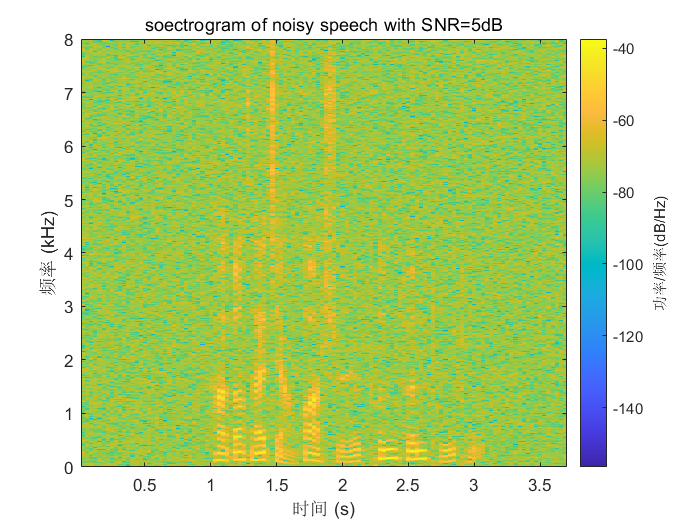

figure
spectrogram(y_5,1000,[],59670,fs,'yaxis');
title('soectrogram of noisy speech with SNR=5dB');

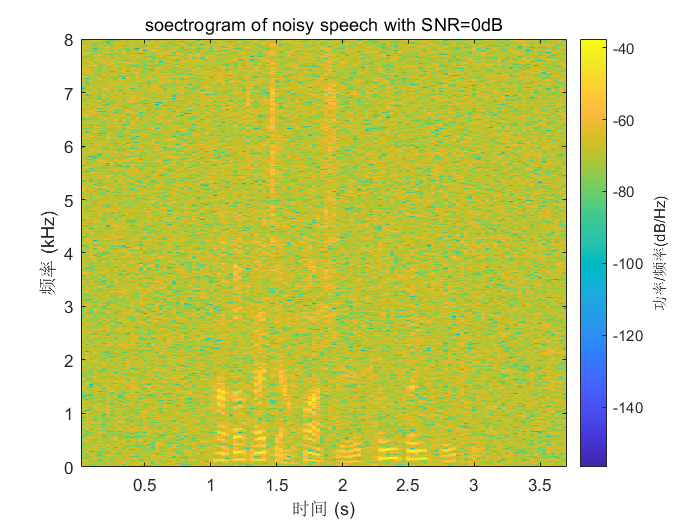

figure
spectrogram(y_0,1000,[],59670,fs,'yaxis');
title('soectrogram of noisy speech with SNR=0dB');